clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

% Casts 
cast01 = readSBScnv( 'ar0701001_hyst.cnv' );
cast02 = readSBScnv( 'ar0701002_hyst.cnv');
cast03 = readSBScnv( 'ar0701003_hyst.cnv' );
cast04 = readSBScnv( 'ar0701004_hyst.cnv' );
cast05 = readSBScnv( 'ar0701005_hyst.cnv' );
cast06 = readSBScnv( 'ar0701006_hyst.cnv' );
cast07 = readSBScnv( 'ar0701007_hyst.cnv' );
cast08 = readSBScnv( 'ar0701008_hyst.cnv' );
cast09 = readSBScnv( 'ar0701009_hyst.cnv' );
cast10 = readSBScnv( 'ar0701010_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

btl = readtable('Irminger_Sea-03_AR7-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year3')
btl05 = readtable('ar0701005_hyst.csv','TextType','string');

btl06 = readtable('ar0701006_hyst.csv','TextType','string');

btl07 = readtable('ar0701007_hyst.csv','TextType','string');

btl08 = readtable('ar0701008_hyst.csv','TextType','string');

btl09 = readtable('ar0701009_hyst.csv','TextType','string');

btl10 = readtable('ar0701010_hyst.csv','TextType','string');


% Join tables 
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");

clear btl0* btl1* btl2*

btlsum_yr3 = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];
btlsum0 = btlsum_yr3; % Dummy summary for removing outliers 

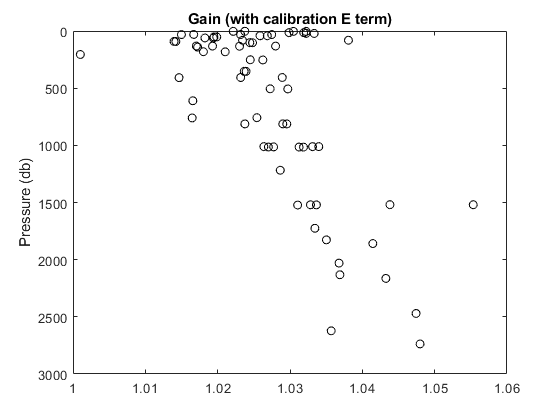

figure
plot(btlsum_yr3.Winkler_mLL./btlsum_yr3.Sbeox0ML_L,btlsum_yr3.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

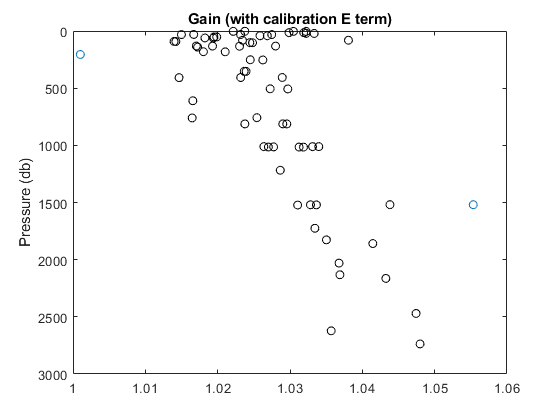

gain0_threshold_low = 1.01;
gain0_threshold_high = 1.05;
gain0 = btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L;
Wink_low = find(gain0 < gain0_threshold_low);
Wink_high = find(gain0 > gain0_threshold_high);
btlsum0.Winkler_mLL(Wink_low) = NaN;
btlsum0.Winkler_mLL(Wink_high) = NaN;

figure
plot(btlsum_yr3.Winkler_mLL./btlsum_yr3.Sbeox0ML_L,btlsum_yr3.PrDM,'o')
hold on
plot(btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(3.79510e-001);
cal.VOFFSET = double(-5.82400e-001);
cal.A = double(-4.14790e-003);
cal.B = double(2.08070e-004);
cal.C = double(-3.05950e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.16000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0338';
cal.OCALDATE = '16-Jan-16';

H = [-0.033, 5000, 1450]; % Default 

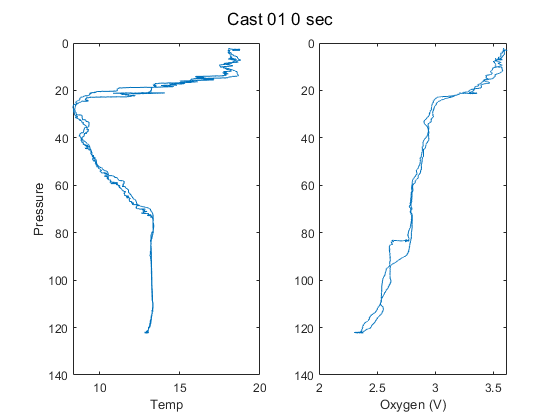

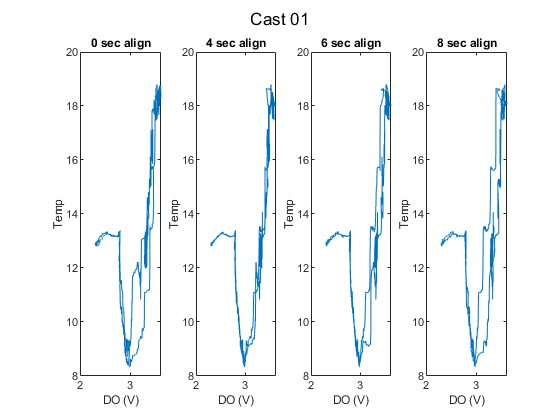

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

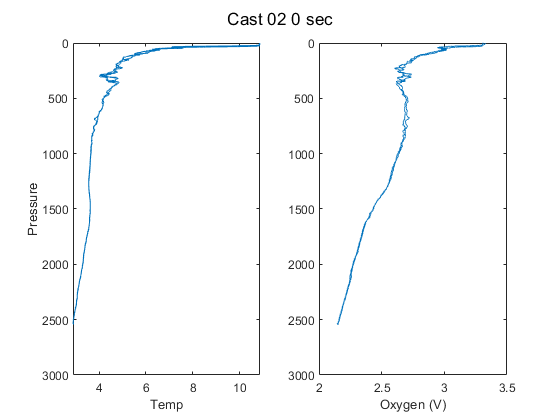

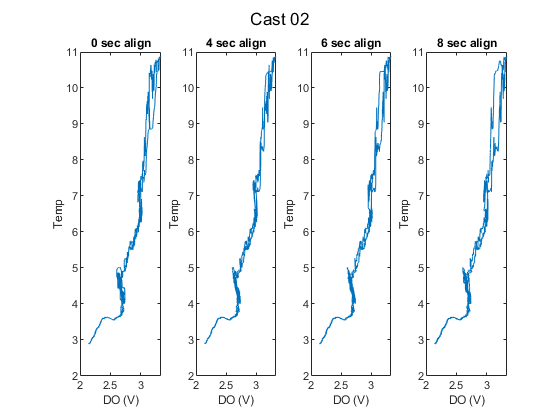

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

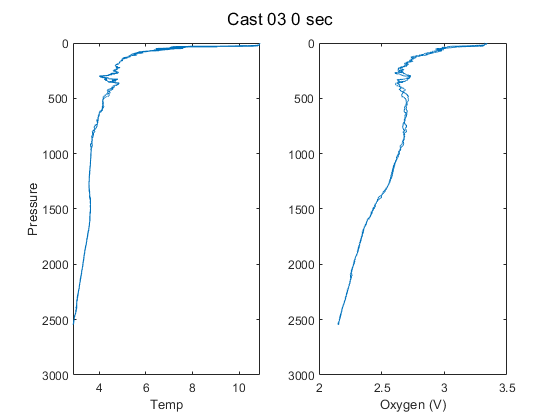

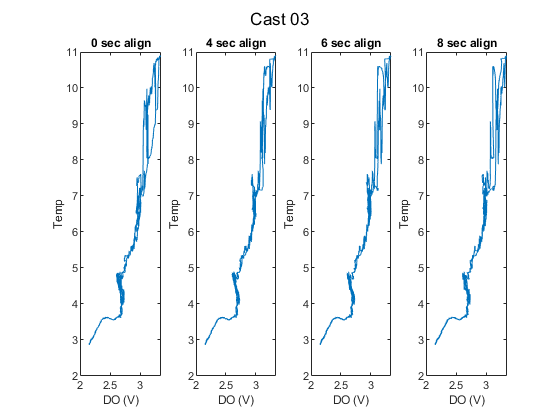

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

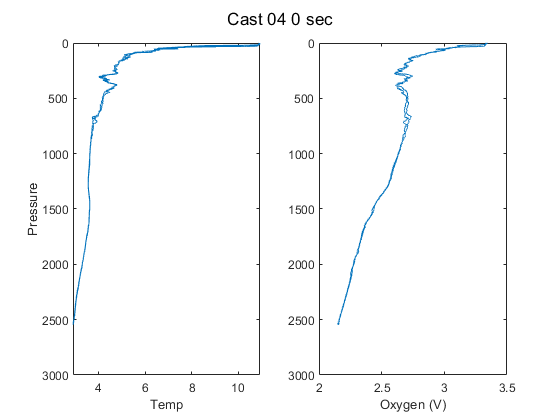

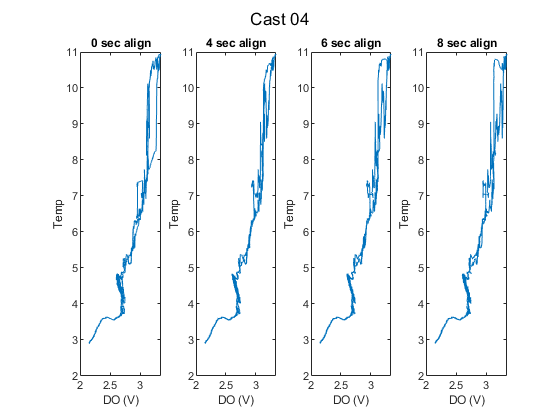

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

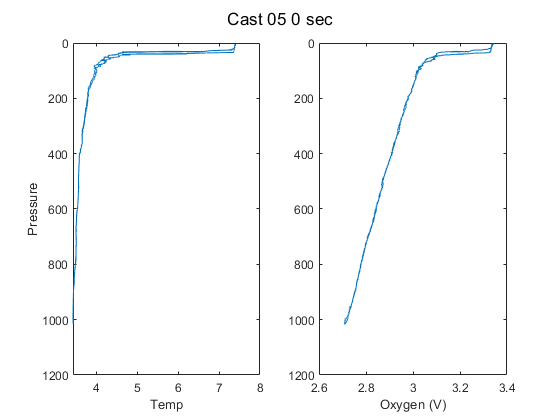

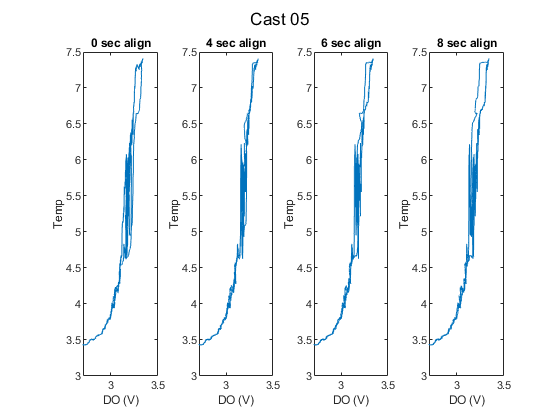

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

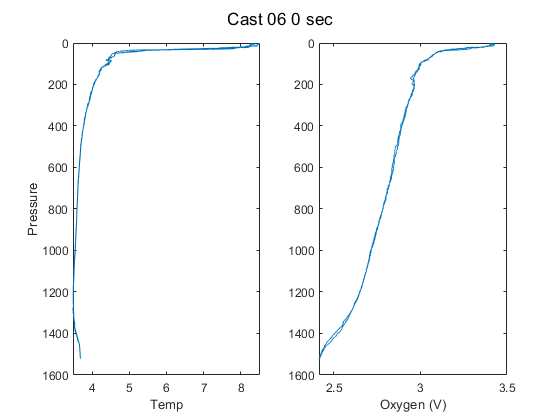

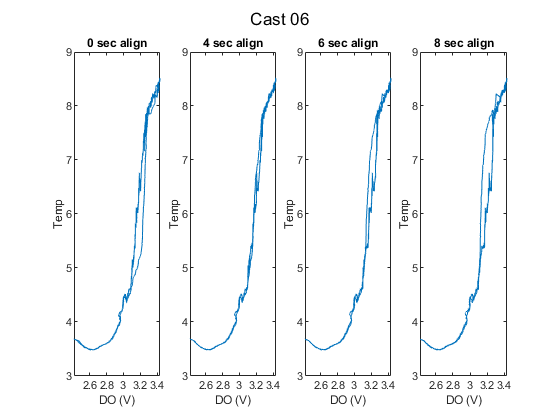

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

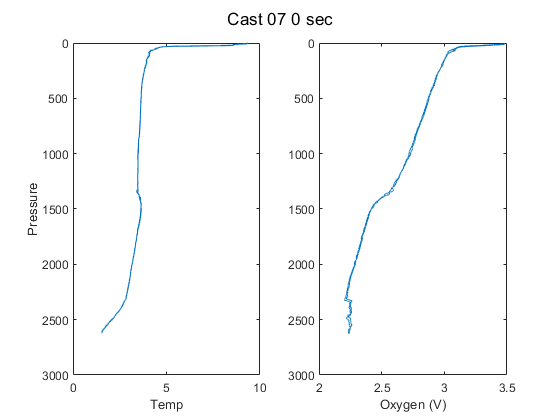

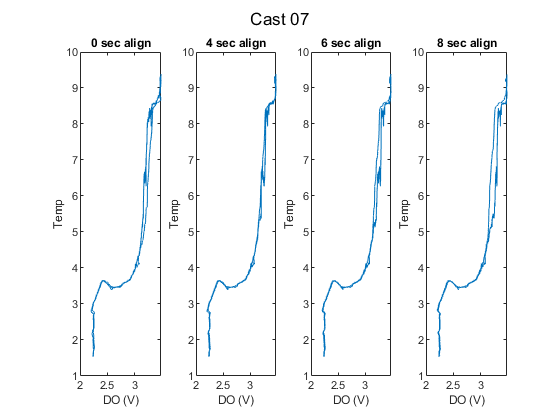

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

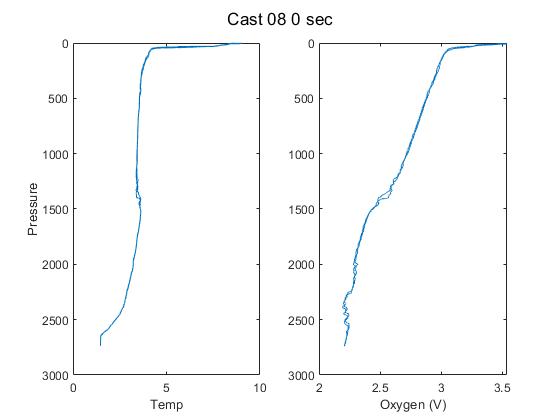

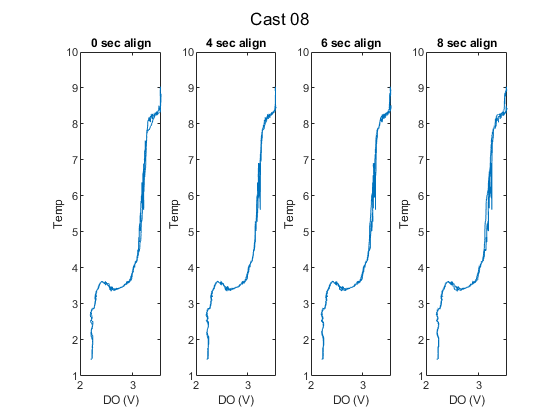

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

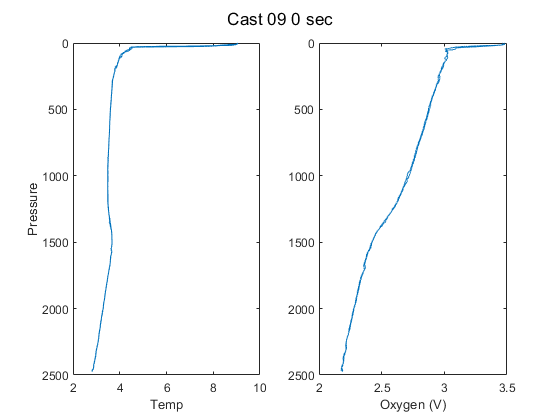

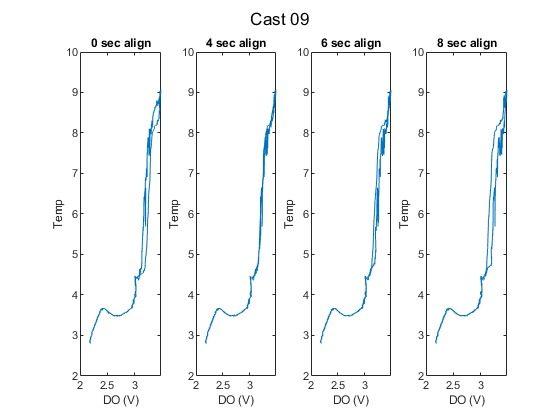

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

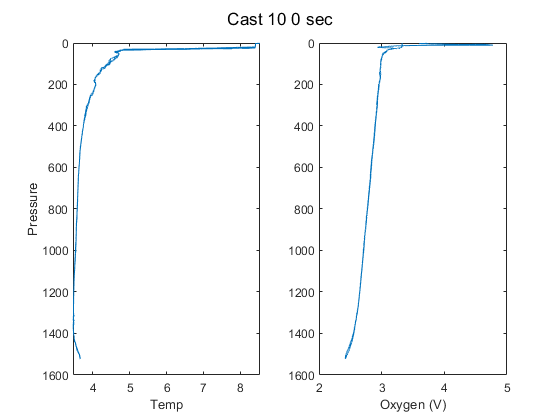

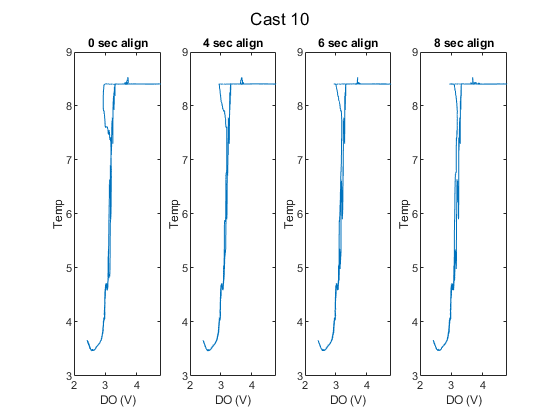

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);


% Pick align_sec

align_sec = a1; 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

% Casts 
cast01 = readSBScnv( 'uar0701001_hyst_abcdefg.cnv' );
cast02 = readSBScnv( 'uar0701002_hyst_abcdefg.cnv');
cast03 = readSBScnv( 'uar0701003_hyst_abcdefg.cnv' );
cast04 = readSBScnv( 'uar0701004_hyst_abcdefg.cnv' );
cast05 = readSBScnv( 'uar0701005_hyst_abcdefg.cnv' );
cast06 = readSBScnv( 'uar0701006_hyst_abcdefg.cnv' );
cast07 = readSBScnv( 'uar0701007_hyst_abcdefg.cnv' );
cast08 = readSBScnv( 'uar0701008_hyst_abcdefg.cnv' );
cast09 = readSBScnv( 'uar0701009_hyst_abcdefg.cnv' );
cast10 = readSBScnv( 'uar0701010_hyst_abcdefg.cnv' );

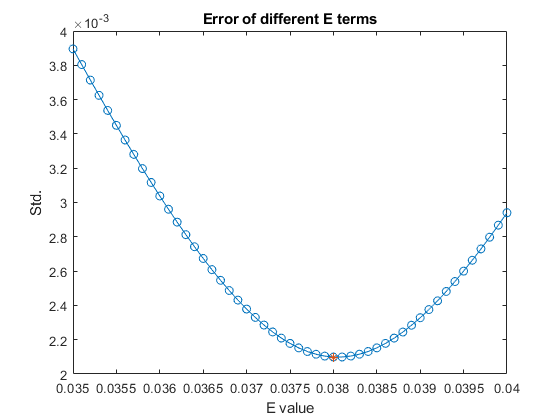

cal.E2 = 0.038


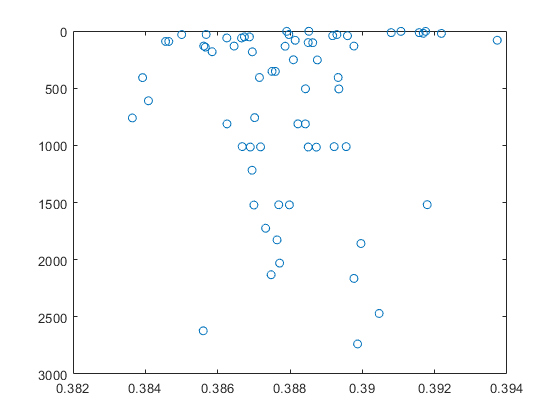

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
[cal] = E2_calculation(btlsum0,cal); % Use dummy bottle summary with outlier removed

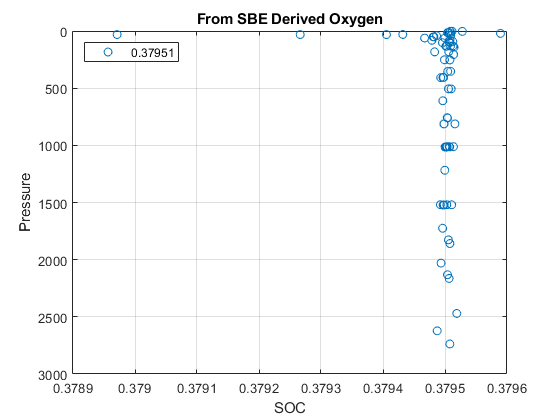

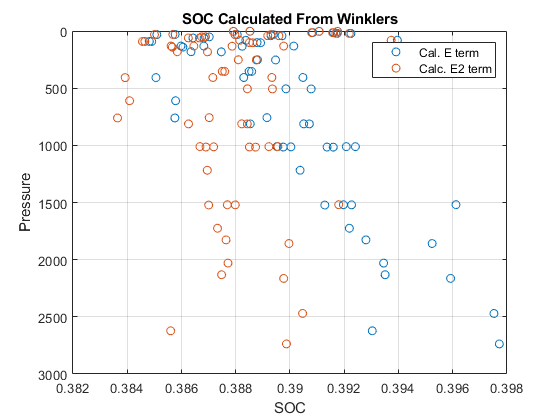

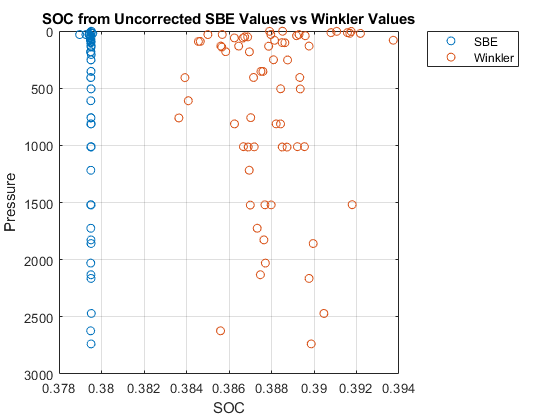

New SOC = 0.38801
EGain = 1.0224+/- 0.0055311


[cal] = Gain_E2_Calculation(btlsum0,cal); % Use dummy bottle summary with any outliers removed

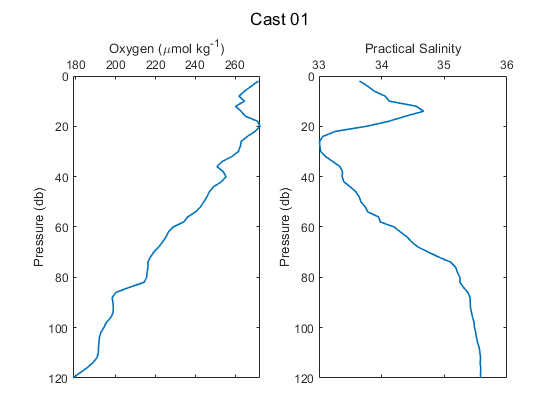

[cast01, btlsum01] = Process_Cast_Gain_E2(cast01,cal,0,1,'Cast 01');

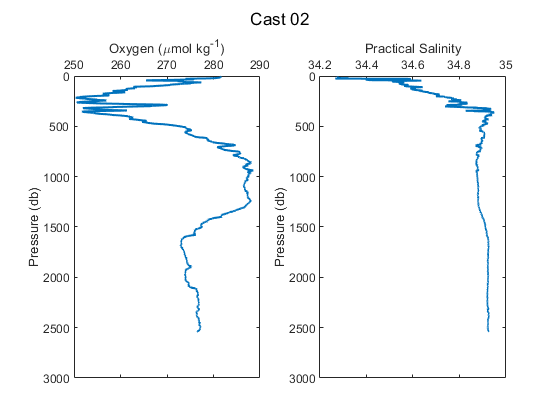

[cast02, btlsum02] = Process_Cast_Gain_E2(cast02,cal,0,1,'Cast 02');

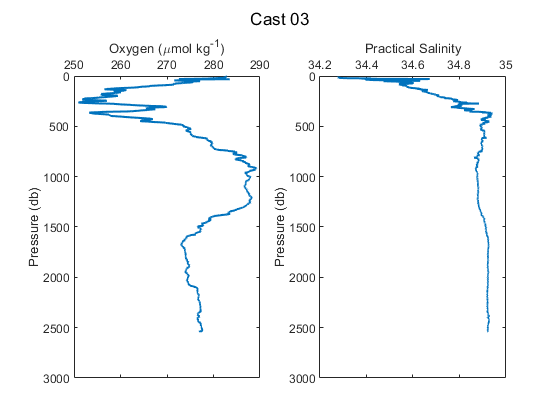

[cast03, btlsum03] = Process_Cast_Gain_E2(cast03,cal,0,1,'Cast 03');

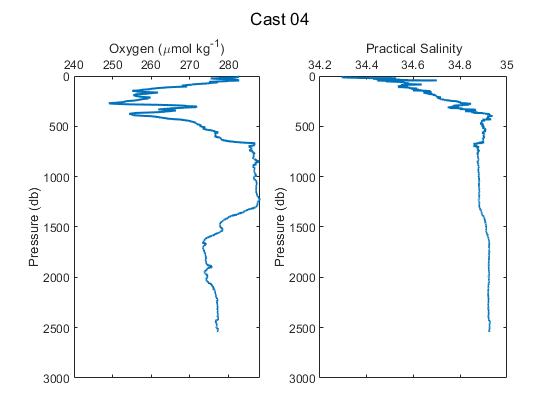

[cast04, btlsum04] = Process_Cast_Gain_E2(cast04,cal,0,1,'Cast 04');

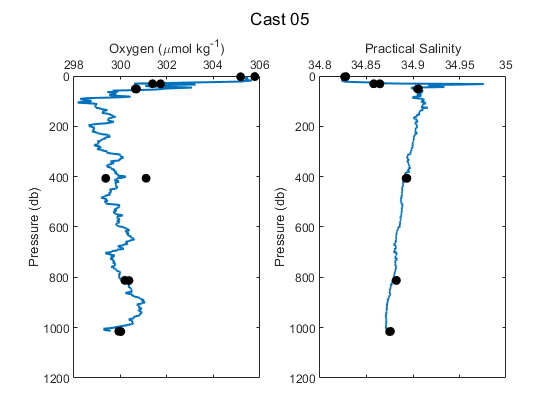

[cast05, btlsum05] = Process_Cast_Gain_E2(cast05,cal,btlsum05,1,'Cast 05');

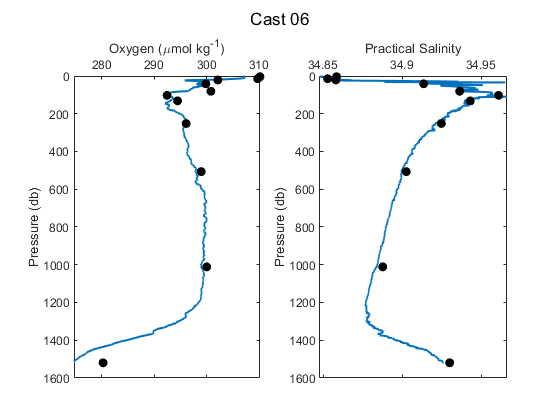

[cast06, btlsum06] = Process_Cast_Gain_E2(cast06,cal,btlsum06,1,'Cast 06');

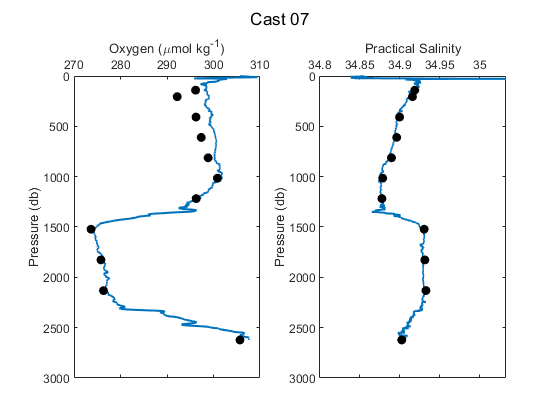

[cast07, btlsum07] = Process_Cast_Gain_E2(cast07,cal,btlsum07,1,'Cast 07');

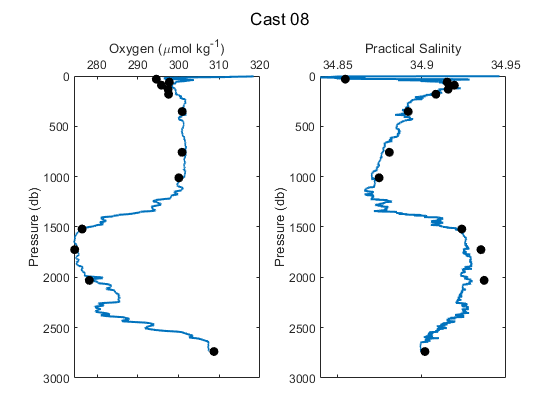

[cast08, btlsum08] = Process_Cast_Gain_E2(cast08,cal,btlsum08,1,'Cast 08');

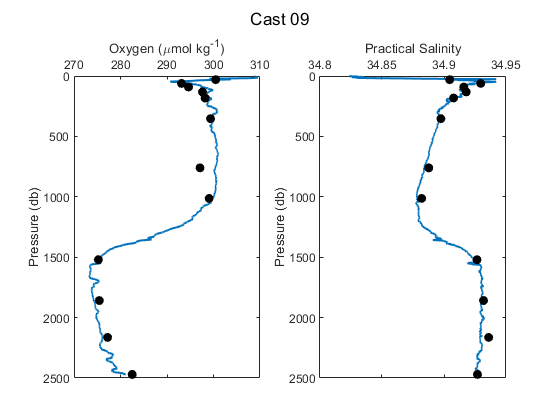

[cast09, btlsum09] = Process_Cast_Gain_E2(cast09,cal,btlsum09,1,'Cast 09');

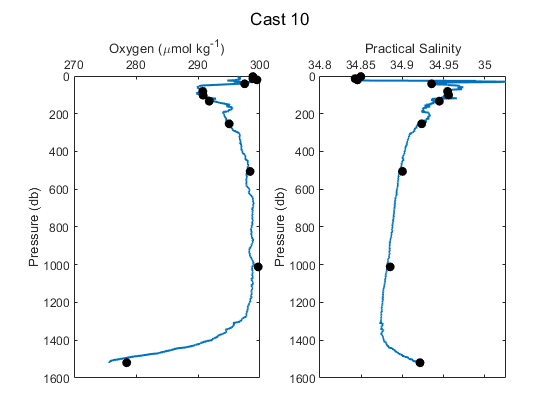

[cast10, btlsum10] = Process_Cast_Gain_E2(cast10,cal,btlsum10,1,'Cast 10');

btlsum_yr3 = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.038


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.37951


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.38801


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.0224+/- 0.0055311


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
clear btlsum0
dt_Processed = datetime;
save Year3_Processed_KF cast* btl* cal* dt_Processed 